%% 3-D example 
% 1. Prameter setting
dim = 3;
knots = [0 2 4 7]; % knots
order = 8; % polynomial order 
optimTarget = 'end-derivative'; % 'poly-coeff' or 'end-derivative'
maxConti = 4; % maximally imposed continuity between segment 
objWeights = [0 1 1];  % 1 2 3 th order derivative
pTraj = PolyTrajGen(knots,order,optimTarget,dim,maxConti); % constructor

Optimization will be performed on end derivatives. This will improve optimization performance.



% 2. Pin 
% 2.1 FixPin 
ts = [0 2 4 7]; % knots
Xs = [0 2 5 7 ; ...
        0 -1 3 -5 ; ...
        0 2 4 5]; % waypoints
Xdot = [ 0 0 0]'; % initial velocity
Xddot = [ 0 0 0]'; % initial acceleration

% Order 0 pin (waypoints)
for m = 1:size(Xs,2)
    pin = struct('t',ts(m),'d',0,'X',Xs(:,m));
    pTraj.addPin(pin);
end   
% Order 1 pin 
pin = struct('t',ts(1),'d',1,'X',Xdot);
pTraj.addPin(pin);
% Order 2 pin 
pin = struct('t',ts(1),'d',2,'X',Xddot);
pTraj.addPin(pin);

% 2.2 LoosePin 
passCube = [3 4.2 ; -3 -2 ; 1 2];
pin = struct('t',3,'d',0,'X',passCube);
pTraj.addPin(pin);

% 3. Solve 
% set the objective function for penalizing the derivatives 
pTraj.setDerivativeObj(objWeights); 
pTraj.solve;

solving 1 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 2 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 3 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
Done!


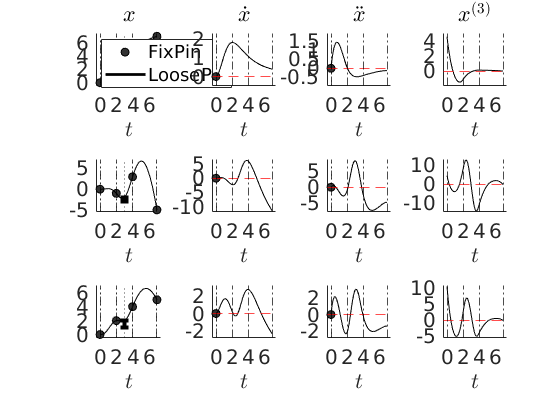


% 4. Evaluate the curve 
t_eval = 3; % evaluation time 
d_eval = 1; % which order to be evaluated for derivative (0,1,2..)
xdot_eval = pTraj.eval(t_eval,d_eval);

% 5. Plot 
figh3 = figure(3); clf
figh4 = figure(4); clf
plotOrder = 3; % Until 3rd order derivatives 
pTraj.showTraj(plotOrder,figh3) % plot element-wise trajectory 

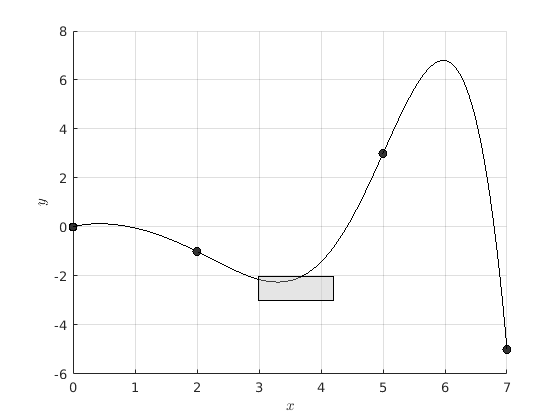

pTraj.showPath(figh4) % 3D path view with pins